# **변경사항**

## 2022.4.8

## 2022.1.15

첫 배포

- `fireRateMaker.m` : `summary_examples_firing_rate.mlx`의 코드를 내장 함수로 가지는 class. `Channel` objet를 입력하면 firing rate histogram을 생성. 특정 이벤트 기준으로 centering하지 않기 때문에 Peri-stimulus time histogram(PSTH)가 아니라 그냥 time histogram(TH) 임. 

- `timeVaryingHeatmap.m`** : **여러 `channel` object를 입력하면 내부적으로 `fireRateMaker` object를 생성하고 time-varying heatmap을 만들거나 동영상 파일로 저장하는 class. 입력된 모든 `channel`의 [시작시간, 종료 시간]의 교집합을 시간 구간으로 함.    

                  *  heatmap 관련 옵션 수정 시, 이 파일의 `makeTimeVaryingHeatmap`, `RecordTimeVaryingHeatmap` 함수를 수정하면 됨

# **주의**

## 경로 추가 관련

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

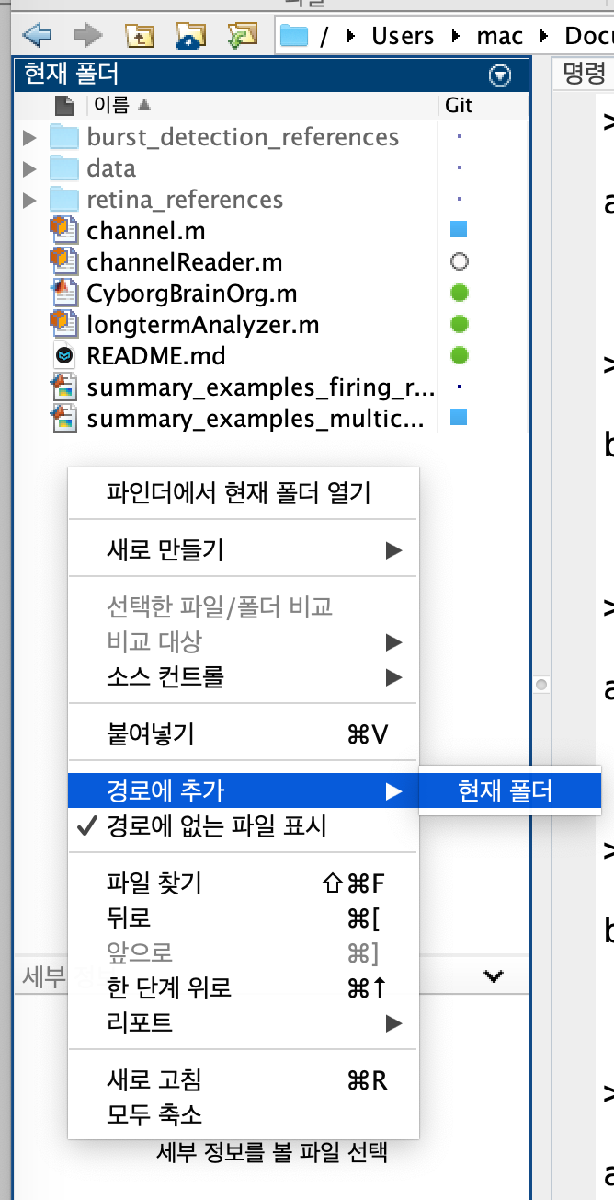

## **1.multi-pixel retina data 불러와 channel object 만들기**

**1.1. 파일 전체를 읽어오기**

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 소요시간 측정. 적지 않은 시간 소요됨

pixel = reader.readManyChannelsFromFile(1, 1)

networkAnalyzer 클래스를 만든다

64개의 채널을 add한다

na = networkAnalyzer();
na.addChannels(reader);
na.bandPass([300,3000])
na.detectSpikes(5,2,2);

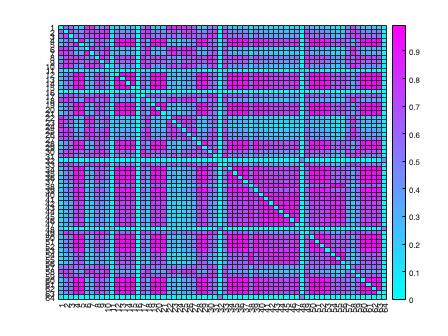

ans =          0    0.6105    0.5321    0.2437    0.2329    0.8116    0.7887    0.3893    0.4531    0.6517    0.1579    0.2397    0.2348    0.2348    0.2377         0    0.4496    0.7368    0.2387    0.2377    0.2358    0.8772    0.8116    0.8235    0.7397    0.7436    0.6170    0.2489    0.2468    0.4328    0.5472         0    0.5524    0.2343    0.2403    0.2414    0.2447    0.1189    0.2569    0.1763    0.1609    0.1538    0.1503    0.1447    0.1383    0.1458    0.1731    0.0645    0.4531    0.2397
    0.6105         0    0.7397    0.4800    0.4615    0.7547    0.7593    0.6882    0.7879    0.7937    0.1067    0.4731    0.4648    0.4577    0.4698         0    0.6867    0.7965    0.4643    0.4626    0.4594    0.5957    0.7358    0.5000    0.7818    0.7652    0.7023    0.4580    0.4706    0.7135    0.7413    0.0294    0.7324    0.4638    0.4741    0.4758    0.4672    0.2480    0.4706    0.3552    0.3377    0.3092    0.2979    0.2972    0.2851    0.2993    0.3495    0.0294    0.7636   

na.spikeDist()

pyrun("import numpy as np; aa = np.array(a)", a = [1,2,3])
pyrun("print(aa)")

[1. 2. 3.]


pyrun("print(aa.dtype)")

float64


G = py.networkx.Graph()
G.add_node(1)
G.add_node(2)
G.add_edge(1, 2, pyargs("weight", 0.5))
G.edges
pos = py.networkx.spring_layout(G)
py.networkx.draw_networkx_edges(G, pos, alpha=0.5)
py.matplotlib.pyplot.savefig(pyargs('/Users/mac/Documents/GitHub/neurosignal-matlab/figure1.png'))


x = py.numpy.arange(25);
y = py.numpy.arange(25);
py.matplotlib.pyplot.plot(x, y)
py.matplotlib.pyplot.title('Sample Data')
py.matplotlib.pyplot.xlabel('x')
py.matplotlib.pyplot.ylabel('y')
py.matplotlib.pyplot.savefig(pyargs('/Users/mac/Documents/GitHub/neurosignal-matlab/figure1.png'))


## **a = 2. **

#### (class) 

**    input:**

#### (method) 

**    input:**

pyenv('Version', "/opt/miniconda3/bin/Python3")

 a= pixel(1)
b = pixel(2)



### **3. 모든 픽셀에 일괄적으로 bandpass filter적용하고 spike detection 수행**

개별 channel object에서 사용하던 함수와 똑같은 방법으로 사용

ani.applyBandPassFilter([300,3000])
ani.detectSpikes(5,2,2)

pixel1 등의 변수명 위에 커서를 올려 보면 bandpass filter, detectSpikes가 적용되었음을 알 수 있다.

pixel1 = pixels{1}

### **4. 모든 픽셀의 spike들에 일괄적으로 cutoff 적용하고, time-varying heatmap 생성**

**(method)**` timeVaryingHeatmap.preProcess`

summary_examples_firing_rate.mlx에서 히스토그램을 그리기 전에 했던 모든 작업을 수행

**    input:**

- `cutoffVal: `특정 측정치 이상의 spike만 고를 때 측정치 기준값

- `binWidth`: firing rate를 측정하는 시간 단위. millisecond.

            % cutoffVal, binWidth(millisecond)
ani.preProcess(5*1e-6, 50) 

**(method)**` timeVaryingHeatmap.makeTimeVaryingHeatmap()`

각 시점의 heatmap을 시간의 흐름에 따라 재생함

**    input:**

- `colormap`: heatmap에서 수치를 색깔로 표현할 때 사용할 colormap

colormap list: https://kr.mathworks.com/help/matlab/ref/colormap.html#d123e146353

%                         colormap
ani.makeTimeVaryingHeatmap(cool)

### **5. time-varying heatmap을 동영상 파일로 저장**

**(method) **`timeVaryingHeatmap.recordTimeVaryingHeatmap()`

mp4파일로 time-varying heatmap을 저장

**    input:**

- `colormap`

- `framerate`:  초당 프레임 수. 총 frame 수는 원본 데이터 시간 길이 / preProcess의 binWidth 변수에 의해 정해짐. 초당 프레임 수를 늘릴수록 동영상이 빨리 재생됨.  총 100프레임이고 framerate를 5로 하면 100/5 = 20초짜리 동영상이 됨 

ani.recordTimeVaryingHeatmap(cool, "test.mp4", 5)

### **6. 모든 픽셀의 firing rate histogram 그리기**

개별 pixel에 접근한 다음, summary_examples_firing_rate.mlx에서 히스토그램 그릴 때 사용했던 edges, psth 변수, selectedSpikeMs 변수를 가져와 히스토그램 및 raster plot을 그림

#### timeVaryingHeatmap object의 구조:

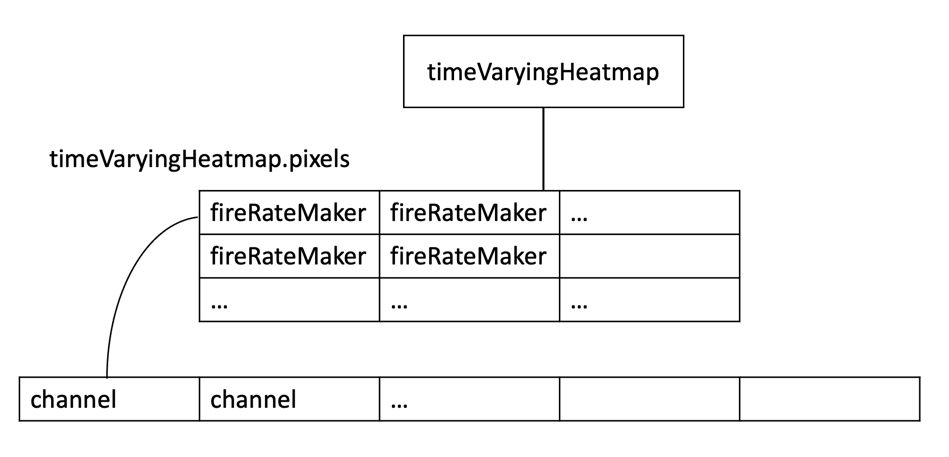

- `timeVaryingHeatmap` object는 `timeVaryingHeatmap.pixels`라는 행렬에 `fireRateMaker` object들을 저장. 

- 각 `fireRateMaker`는 한 개 혹은 여러개의 `channel `object를 저장

- firing rate histogram 정보는 각` fireRateMaker `object에 저장되어 있음

- 하나의 pixel slot에 속한 각 `channel`의 spike timestamp 정보는 `fireRateMaker` object에 selectedMs라는 list로 저장되어 있음

-> `fireRateMaker` object에만 접근하면 histogram, raster plot 다 그릴 수 있음

**그래프 옆의 화살표(figure 창에서 열기)를 누르고 새 창을 전체화면으로 키워야 그래프가 잘 보임**

figure;

for rowIdx = 1:8
    for colIdx = 1:8
        pixelNow = ani.pixels{rowIdx, colIdx}; %개별 pixel slot에 접근. fireRateMaker 오브젝트를 얻게 됨
        
        % histogram 정보는 fireRateMaker object에 저장되어 있음
        thNow = pixelNow.th;
        edgesNow = pixelNow.edges;
        subplot(8, 8, (rowIdx - 1)*8 + colIdx )
         bar(edgesNow,thNow); %Plot as a bar graph 

        % spike raster plot 관련 정보는 fireRateMaker object 내의 selectedMs에 저장됨
        selectedSpikesMs = pixelNow.selectedMs{1}; %pixel slot마다 channel을 하나만 넣었으므로 첫 번째 원소만 존재함.
        for i = 1:length(selectedSpikesMs) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
            line([selectedSpikesMs(i) selectedSpikesMs(i)], [0.9, 1])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
        end
        
    end
end

%그래프 하나 빼고 축 전부 제거
t = get(get(gcf, 'Children'), 'XAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
t = get(get(gcf, 'Children'), 'YAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
set(get(gcf, 'Children'), 'Color', 'none')


## 7. section 6의 히스토그램이 제대로 그려졌는지 확인하기 위해, 4번째 pixel의 히스토그램을 class 없이 그려 보기

data1 = reader.readSingleChannelFromFile(1, 4, 1);
data1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
data1.detectSpikes(5,2,2);
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 5*1e-6; % apply the cutdoff. the result looks like (true, true, false, true, false,...)
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean); %apply the boolean and get the selected spikes
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

edges = [data1.startTime*1000: 50: data1.endTimeApprox*1000]; %시작점 : 구간길이 : 끝점
th = zeros(length(edges),1)'; %Initialize the PSTH with zeros
th = th + histc(data1SelectedMs,edges);
th = th / 50; %firing rate

figure
bar(edges,th); %Plot PSTH as a bar graph 
xlim([min(edges), max(edges)]);%Set limits of X-axis 
xlabel('Time (sec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

## 8. **모든 픽셀의 filtered signal trace 그리기**

signal data는 fireRateMaker object에는 저장되지 않고, channel object까지 접근해야 얻을 수 있음

**그래프 옆의 화살표(figure 창에서 열기)를 누르고 새 창을 전체화면으로 키워야 그래프가 잘 보임**


figure;

for rowIdx = 1:8
    for colIdx = 1:8
        channelNow = ani.pixels{rowIdx, colIdx}.channels{1}; %channel object를 각 slot마다 하나씩만 넣었으므로, 첫 번째 channel만 사용해도 됨
        
        subplot(8,8,(rowIdx - 1) * 8 + colIdx )
        plot(channelNow.t, channelNow.filtered); %matlab 기본 plot 함수 사용

        ylim([-6,6]*1e-4);%ylim 조절 가능

        end
end
%그래프 하나 빼고 축 전부 제거
t = get(get(gcf, 'Children'), 'XAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
t = get(get(gcf, 'Children'), 'YAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
set(get(gcf, 'Children'), 'Color', 'none')